## 相关系数

1.样本均值--总体均值（平均水平）

2.样本标准差--总体标准差（偏离程度）

3.皮尔逊(Person)相关系数

4.总体协方差--反应两数据相关性（受量纲影响）Cov(X, Y)

        A.正数：正相关

        B.负数：负相关

        C:接近 0：不相关

5.皮尔逊相关函数--总体协方差 / 个数据的标准差的乘积  （剔除了两个变量量纲的影响）

        | $P_{\textrm{xy}}$ | <= 1

        用来衡量两个变量线性相关程度

        A.正数：正相关

        B.负数：负相关

        C:接近 0：不相关，不是线性相关（可能是其他相关）

        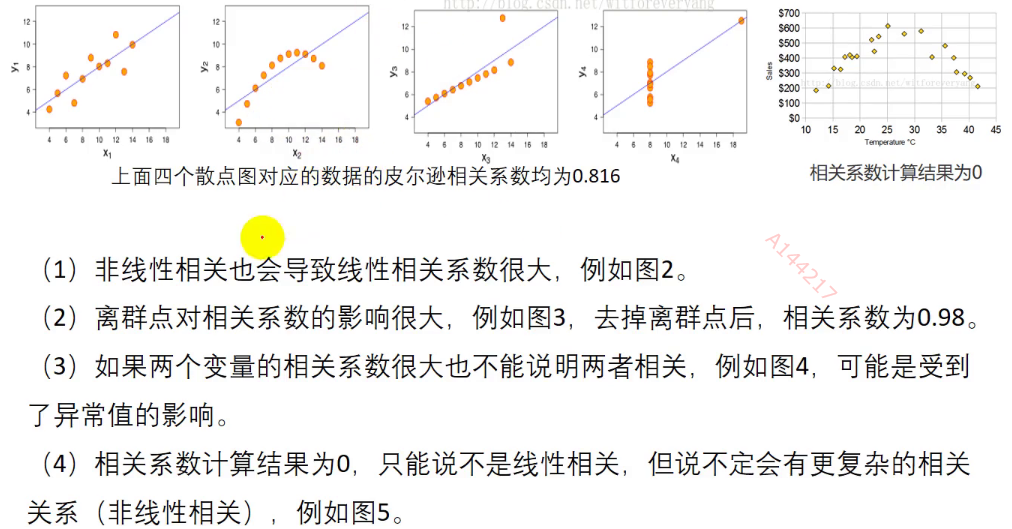

6.在计算皮尔逊相关系数之前，一定要做出散点图看两组变量之间是否有线性相关

7.spss软件：图形，旧对话框，散点图/点图，矩阵散点图

clc
clear

load 'A.mat'

A_min = min(A);  % 计算每一列的最小值
A_man = max(A);  % 最大值
A_mean = mean(A);  % 平均值
A_med = median(A);  % 中位数
A_ske = skewness(A);  % 偏度
A_kur = kurtosis(A);  % 峰度
A_std = std(A);  % 标准差

% 保存到一个矩阵
A_data = [A_min; A_man; A_mean; A_med; A_ske; A_kur; A_std];

% 计算各列之间的相关系数
A_R = corrcoef(A);

## 假设检验

1.显著性水平（$\alpha$）：原假设犯错的概率（即本来是对的，以为错了）

2.置信水平（$\beta$ = 1 - $\alpha$）：相信原假设成立的概率（一般  90%  95%  99%）

3.双侧检验、单测检验 

4.步骤

        A.确定原假设 H0 和备择假设 H1

        B.根据数据构造一个分布（标准正态分布、t 分布、F 分布、$X^2$ 分布）

        C.画出概率密度图

        D.给置信水平（95% 最多）

        E.用已知的数据带入样本数据带入计算统计量，得到检验值

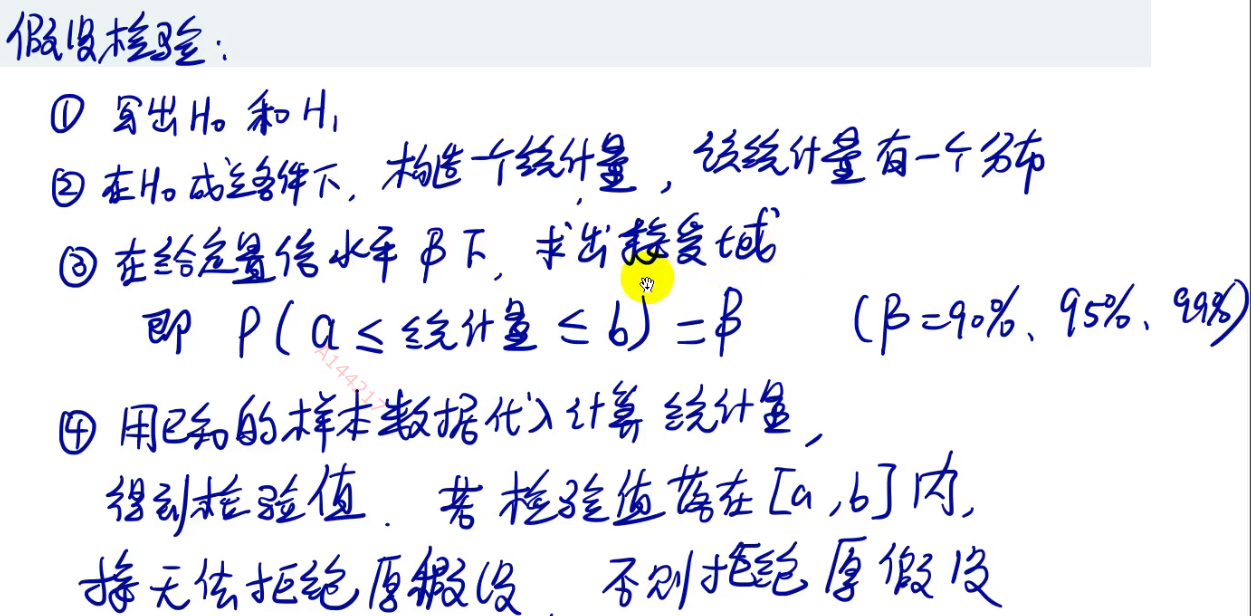

5.概率密度函数 pdf

6.累积密度函数

7.双侧检验 p 值是单侧检验的两倍

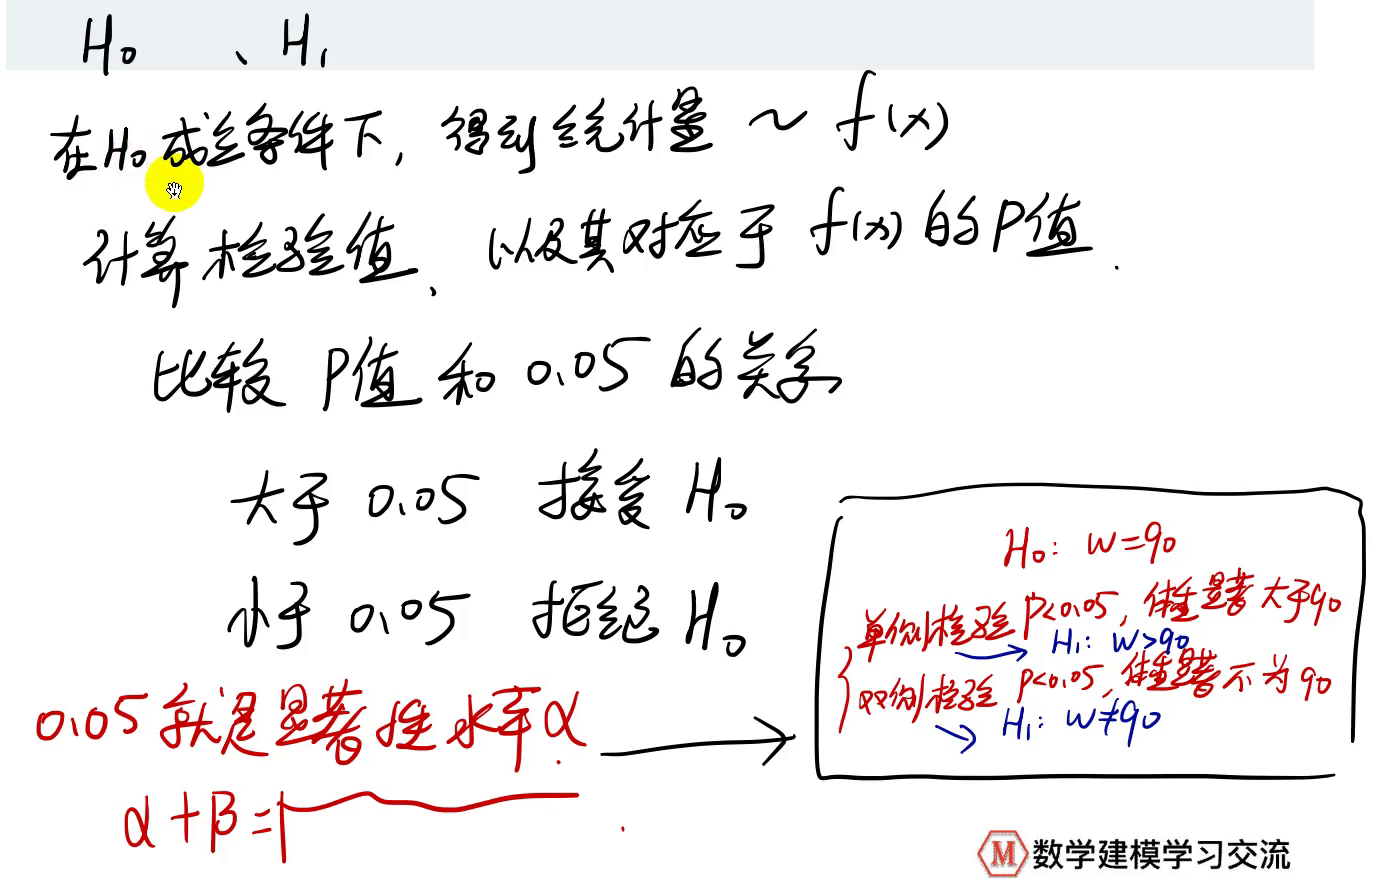

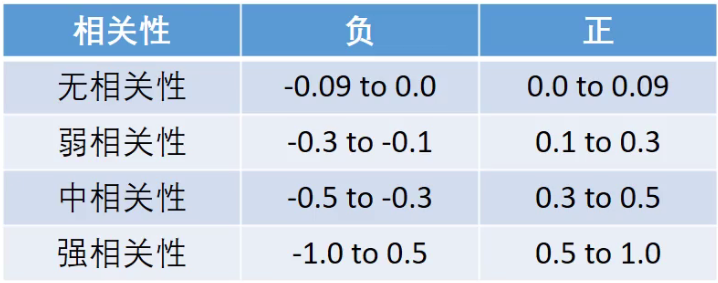

8.皮尔逊相关系数假设检验的条件

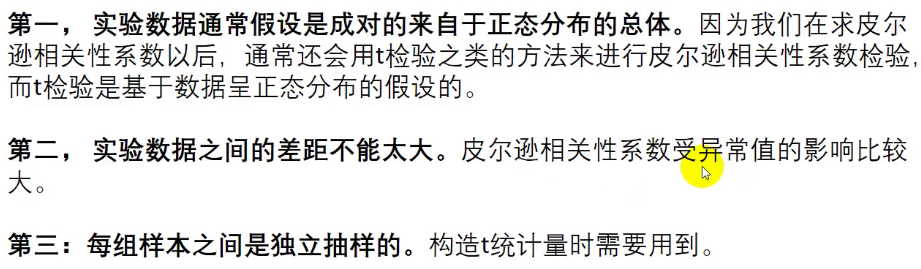

9.偏度和峰度

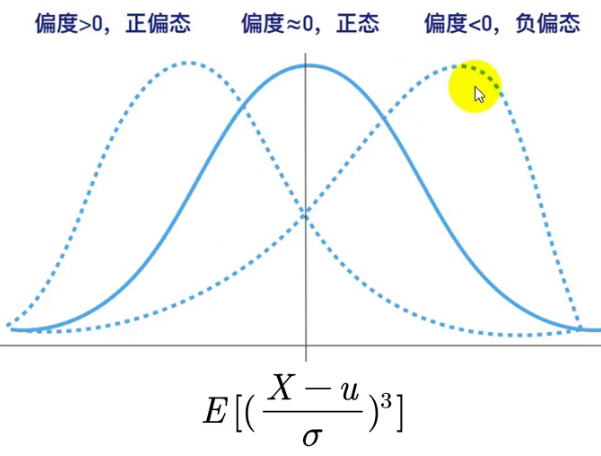       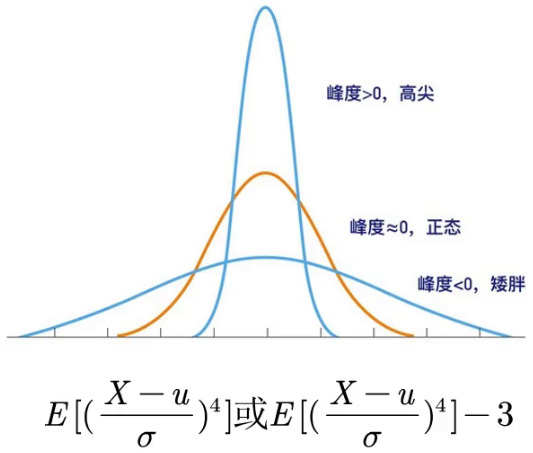

10.正态分布 JB 检验（n > 30， 正态分布的偏度为 0， 峰度为 3）

        A.样本服从正太分布时，JB~$x^2 \left(2\right)$（自由度为 2 的卡方分布）

11.夏皮洛-威尔克检验

        A.使用于小样本，1 <= n <= 50

        B.使用 spss 软件

        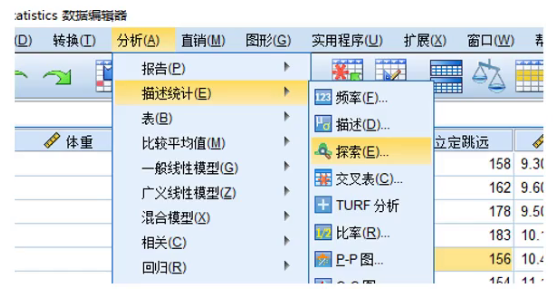          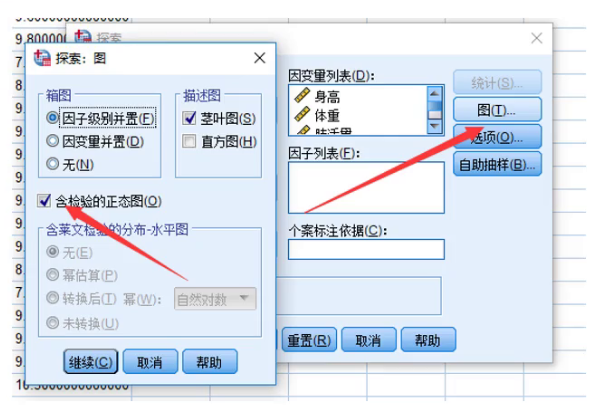

12.斯皮尔曼相关系数（使用于小样本情况 3 <= n <= 50）

           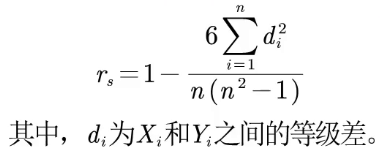     

            等极差：一列数按照从小到大排序后，这个数所在的位置，如果数值相同，则取平均

            正负数：正负相关   0--不相关

            $r_s$ 位于 -1 和 1 之间

        斯皮尔曼相关系数可以被定义为等级之间的皮尔逊相关系数

        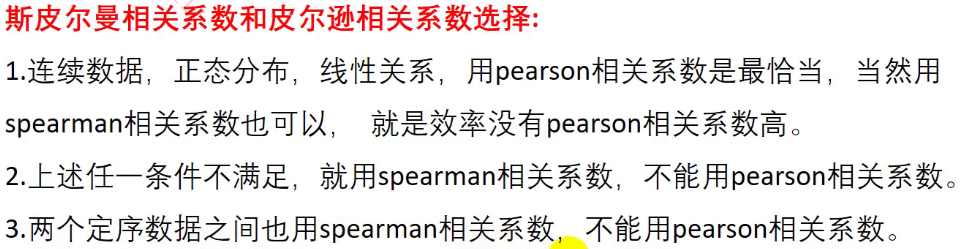

x = -4 : 0.1 : 4;
y = tpdf(x, 28);  % 求 t 分布的概率密度值  28 为自由度
figure(1)  % 给图编号
plot(x, y, '-')  % 画 t 分布的概率密度图
xlabel('x')
ylabel('概率密度')
grid on  % 加网格线
hold on  % 保留原来的图

% 画概率密度图（标明区域）
f_tinv = tinv(0.975, 28)  % 求概率对应的临界值，为累计函数 tcdf 的反函数

f_tinv = 2.0484

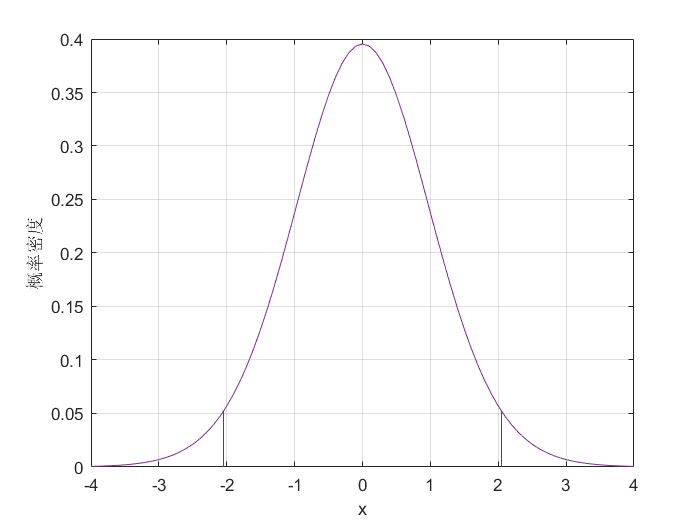

plot([-f_tinv, -f_tinv], [0, tpdf(-f_tinv, 28)], 'r-')
plot([f_tinv, f_tinv], [0, tpdf(f_tinv, 28)], 'r-')


% 计算 p 值
figure(2)
disp('该检验值对应的p值为：')

该检验值对应的p值为：


disp((1 - tcdf(f_tinv, 28)) * 2)  % 双侧检验的 p 值要乘以 2

    0.0500




% 计算各列之间的相关系数以及 p 值（标星，spps 更方便）
[R, P] = corrcoef(A)  % 获取相关系数和 P 置   R--相关系数（应该是皮尔逊相关系数）   P--P 值

R =     1.0000    0.0665   -0.2177   -0.1920    0.0440    0.0951
    0.0665    1.0000    0.0954    0.0685    0.0279   -0.0161
   -0.2177    0.0954    1.0000    0.2898    0.0248   -0.0749
   -0.1920    0.0685    0.2898    1.0000   -0.0587   -0.0019
    0.0440    0.0279    0.0248   -0.0587    1.0000   -0.0174
    0.0951   -0.0161   -0.0749   -0.0019   -0.0174    1.0000


P =     1.0000    0.1061    0.0000    0.0000    0.2859    0.0208
    0.1061    1.0000    0.0204    0.0960    0.4978    0.6963
    0.0000    0.0204    1.0000    0.0000    0.5469    0.0687
    0.0000    0.0960    0.0000    1.0000    0.1542    0.9637
    0.2859    0.4978    0.5469    0.1542    1.0000    0.6728
    0.0208    0.6963    0.0687    0.9637    0.6728    1.0000


P = 0.01  % 3 星的位置
(P < 0.05) .* (P > 0.01)  % 2 星的位置
(P < 0.1) .* (P > 0.05)  % 1 星的位置


% 正态分布检验
x = normrnd(2, 3, 100, 1);  % 生成 100 * 1 的随机向量，均值 2， 标准差 3 的正太分布
x_ske = skewness(x)  % 偏度

x_ske = -0.1656

x_krt = kurtosis(x)  % 峰度

x_krt = 2.8749

qqplot(x)  % QQ图，近似直线--正态分布，数据量要在几百以上

% 检验第一列数据是否为正态分部
[h, p] = jbtest(A(:, 1), 0.05)  % h = 1, 拒绝原假设

h = 1

p = 0.0110

[h, p] = jbtest(A(:, 1), 0.01)  % h = 0, 不能拒绝原假设

h = 0

p = 0.0110


% 用循环检验所有列的数据
n_c = size(A, 2);  % number of column 数据的列数
H = zeros(1, 6);  % 初始化节省时间和消耗
P = zeros(1, 6);
for i = 1 : n_c
    [h, p] = jbtest(A(:, i), 0.05);
    H(i) = h;
    P(i) = p;
end

disp(H)

     1     1     1     1     1     1



disp(P)

    0.0110    0.0010    0.0136    0.0010    0.0010    0.0393



qqplot(A(:, 1))


% 斯皮尔曼相关系数
X = [3 8 4 7 2]';
Y = [5 10 9 10 6]';

prs = 1 - 6 * (1 + 0.25 + 0.25 + 1) / 5 / 24

prs = 0.8750


% 第二种方法计算斯皮尔曼相关系数
coeff = corr(X, Y, 'type', 'Spearman')

coeff = 0.8721

R = corr(A, 'type' , 'Spearman')  % 计算矩阵各列的斯皮尔曼相关系数

% 等价于---(不懂)
RX = [2 5 3 4 1];
RY = [1 4.5 3 4.5 2];
R = corrcoef(RX, RY)

R =     1.0000    0.8721
    0.8721    1.0000


R =     1.0000    0.0301   -0.2430   -0.1990    0.0624    0.1099
    0.0301    1.0000    0.1305    0.0898    0.0216   -0.0488
   -0.2430    0.1305    1.0000    0.2626    0.0219   -0.0801
   -0.1990    0.0898    0.2626    1.0000   -0.0910   -0.0029
    0.0624    0.0216    0.0219   -0.0910    1.0000   -0.0399
    0.1099   -0.0488   -0.0801   -0.0029   -0.0399    1.0000



disp(sqrt(590) * 0.0301)  % 大样本下的假设检验 计算检验值

    0.7311




[R, P] = corr(A, 'type', 'Spearman')  % 直接给出相关系数和 p 值

R =     1.0000    0.0301   -0.2430   -0.1990    0.0624    0.1099
    0.0301    1.0000    0.1305    0.0898    0.0216   -0.0488
   -0.2430    0.1305    1.0000    0.2626    0.0219   -0.0801
   -0.1990    0.0898    0.2626    1.0000   -0.0910   -0.0029
    0.0624    0.0216    0.0219   -0.0910    1.0000   -0.0399
    0.1099   -0.0488   -0.0801   -0.0029   -0.0399    1.0000


P =     1.0000    0.4647    0.0000    0.0000    0.1295    0.0075
    0.4647    1.0000    0.0015    0.0290    0.5996    0.2362
    0.0000    0.0015    1.0000    0.0000    0.5944    0.0517
    0.0000    0.0290    0.0000    1.0000    0.0270    0.9436
    0.1295    0.5996    0.5944    0.0270    1.0000    0.3330
    0.0075    0.2362    0.0517    0.9436    0.3330    1.0000


### 皮尔逊相关

A = 1 : 1 : 10;
B = 1 : 2 : 20;

[r, t] = pearson(A, B)

r = 1

t = 0.7071

### 斯皮尔曼相关

A = 1 : 1 : 10;
B = 1 : 2 : 20;

B(3) = 10;

[r, t] = spearman(A, B)

r = 0.9636

t = 10.1999